%{
Name: Profit vs Production 
Author: Evan Scheuritzel
Version: 1.0
Purpose: Determine the most profitable market saturation for a product.
Input: none
Output: Graph showing estimaged costs revenue and costs.
%}

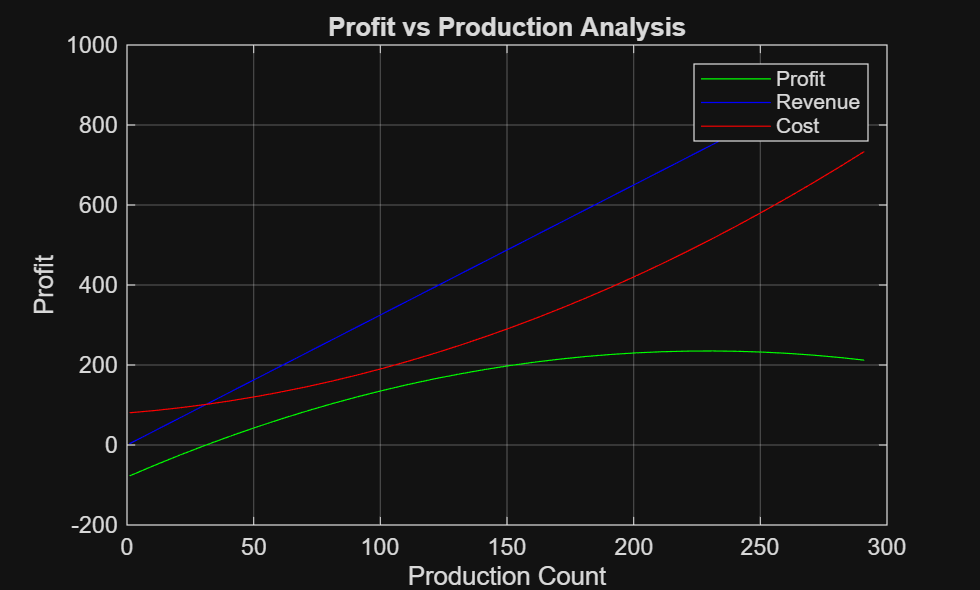

clear
%Cost and revenue numbers
a = 0.006;
b = .5;
c = 80;
p = 3.25;

x = 1:10:300;
R = p*x;
C = a*x.^2 + b*x+c;
P = R-C;
plot(x,P,'green')
hold on
plot(x, R,'blue')
plot(x, C,'red')
grid on;
xlabel('Production Count');
ylabel('Profit');
title('Profit vs Production Analysis');
legend('Profit', 'Revenue', 'Cost');

% Display the maximum profit and corresponding production count
[maxProfit, idx] = max(P);
optimalProduction = x(idx);
fprintf('Maximum Profit: %.2f at Production Count: %.2f\n', maxProfit, optimalProduction);

Maximum Profit: 235.08 at Production Count: 231.00


% Calculate the break-even points
breakEvenPoints = find(R >= C,1,"first");
fprintf('Break-even production counts: %s\n', num2str(x(breakEvenPoints)));

Break-even production counts: 41
